# Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Obtain SAR Data

SAR data from Sentinel-1A can be downloaded from [Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home). In order to download data, you need to register an account on the site.

Once you have registered your account, you can search for SAR data on the site by choosing the appropriate filters and region. The region you search is set by right-clicking and drawing a rectangle, otherwise you can left-click and draw the vertices of any polygon. Recomended filters are:

- **Sensing Period: **As desired

- **Satellite Platform:** S1A

- **Product Type:** GRD

- **Polarisation:** As desired

After searching with your filters, you will see all the available data within this region. Clicking on a red footprint on the map, shows a preview of these data, and the data can be downloaded from the pop-up. 

*Note: *These data are in excess of 1GB, so large amounts of storage space is required. Use an external hard drive if possible.

## **Pre-Process SAR Data**

After downloading SAR data from [Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home), open SNAP and import the data. These data can be viewed as follows:

- Click the '+' next to the dataset

- Click the '+' next to the *Bands* folder

- Open the desired band to preview the image

### Thermal Noise Calibration

**This needs to be done first**

To remove thermal noise, click *Radar -> Radiometric -> S1 Thermal Noise Removal. *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that *Remove Thermal Noise* is checked in the *Processing Parameters* window

- Select a specific polarisation - should be VV or HH

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin removing thermal noise from the selected data and once complete will open in the *Product Explorer *sidebar.

### Radiometric Calibration

To radiometrically calibrate the SAR data, ensure that the **noise calibrated product is selected**, then click *Radar -> Radiometric -> Calibrate *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that **only** *Output sigma0 band* is checked in the *Processing Parameters* window

- Select a specific polarisation - should be VV or HH

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin radiometric calibration from the selected data and once complete will open in the *Product Explorer *sidebar.

### Creating bands

- Click on the 'v' next to the *Tie-Point Grids* folder

- Right click on 'incident_angle'

- Select *Band Maths...*

- Name the new band 'i_angle'

- Click *ok*

- Click on the 'v' next to the *Bands* folder

- Right click on the *i_angle *virtual band

- Select *Convert Band*

- Repeat this process for the 'slant_range_time' tie-point grid but name it 'slant_range_t'.

### Exporting as NetCDF

In order to export these pre-processed SAR data in a format supported by MATLAB, the following process needs to be followed.

- Click *File*

- Hover over the *Export* option, and select **NetCDF4-BEAM**

- If your file explorer is opened, click on *Subset... *on the right hand side of the dialog box

- This will bring up a new window with four different menus.

- You can take a Spatial Subset of the image using either pixel or geographical coordinates in the *Spatial Subset *menu

- Ensure that under the *Band Subset* menu, your desired bands are selected, as well as your created ***i_angle, slant_range_time***, ***Lat and Lon***** bands. **

- Ensure that under the *Metadata Subset* menu, all options are selected

- After checking all of these parameters, click OK, and name the file as desired and save it in your desired location

****TO DO:** Remove the need for this step. Do preprocessing in MATLAB..

## 0 Import Libraries

waveLibrary = waveLibrary;
handh = hAndH1991Library;
transectFunctions = transectLibrary;
plotFunctions = plotLibrary;

## 1 Import the Sentinel-1A Data

### 1.1 Import from file

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "/Users/tris/Documents/MSc/Data/Cape Point/subset_0_of_S1A_IW_GRDH_1SDV_20241014T173427_T173452_tnr_Cal_msk.nc";

% Import metadata information for ease of figuring out where everything is
% stored (this is just a dev step)
% ncInfo_SAR = ncinfo(filepath); 

% Create a sentinel 1A satellite object to store all important information.
sentinel = Sentinel1A(filepath);

% Import the data.
sar_latGrid = sentinel.getLatitudeGrid;
sar_lonGrid = sentinel.getLongitudeGrid;
sar_data = sentinel.getCalibratedSARImage("VV");

sar_start_datetime = sentinel.AcquisitionStartDatetime; 
sar_stop_datetime = sentinel.AcquisitionStopDatetime; 

% TO DO: Investigate the affect of using the original vs using the SNAP
% values. Does it make that big of a difference?
useOriginalS1AHeading = false;
if useOriginalS1AHeading
    sar_azimuth_to_north_angle = sentinel.PlatformHeading;
else 
    sar_azimuth_to_north_angle = sentinel.azimuthToNorthAngleConversion;
end

sar_dy_azimuth = sentinel.AzimuthResolution;
sar_dx_range = sentinel.RangeResolution;


### 1.2 View SAR Data

Choose whether to display an image of the imported SAR data.

plotSARData = false;
if plotSARData
    figure; plotFunctions.sarImage(1, sar_data, "Sentinel 1A SAR Image - 14 October 2024");
end

## 2 Open Ocean Transect

Wave buoy lcation: https://wavenet.csir.co.za/OnlineData/CapeTown/ct_m.htm

wave_buoy_lat = -34.204;
wave_buoy_lon = 18.28666944;

This transect needs to be absent of any ice i.e. completely open ocean.

****TO DO**: Come up with a smart way of doing open ocean detection when selecting the first transect. 

sar_transect_size = 512; % This is the standard size used.
sar_sub_transect_size = 128;

### **2.1 Define Points of Interest / Transect**

These are the top left corner point of the OO transect.

latitude_of_interest = wave_buoy_lat;
longitude_of_interest = wave_buoy_lon;

### 2.2 Create the OO Transect

Now we need to find the indexes. Note that in matlab dimension are row by columns = y by x = latitude by longitude

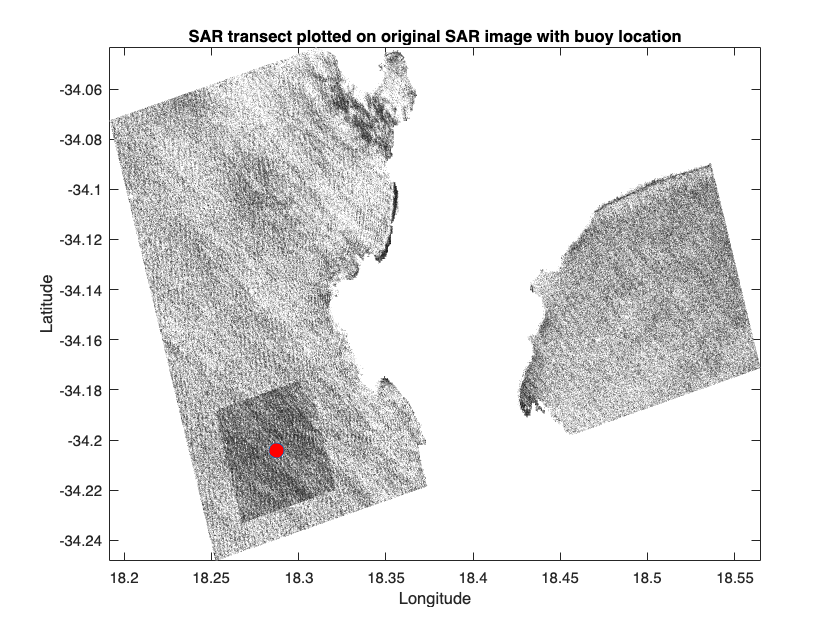

[sar_transect_data,sar_transect_lonGrid,sar_transect_latGrid,sar_transect_center_longitude, sar_transect_lon_indices,sar_transect_center_latitude,sar_transect_lat_indices] = transectFunctions.transectFromSARImage(latitude_of_interest,longitude_of_interest,sar_latGrid,sar_lonGrid,sar_data, sar_transect_size);

% Plot the transect
% figure; plotFunctions.sarTransect(sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid, "SAR transect");
% figure; plotFunctions.sarTransectWithBuoy(sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid, wave_buoy_lon, wave_buoy_lat, "SAR transect with wave buoy location");
% figure; plotFunctions.sarTransectOnSARImage(sar_Data(2000:4000,3000:6000), sar_latGrid(2000:4000, 3000:6000), sar_lonGrid(2000:4000, 3000:6000), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid, "SAR transect plotted on original SAR image");
%TO DO: FIND A WAY TO NOT HAVE TO HARDCODE THE TRANSECT
figure; plotFunctions.sarTransectOnSARImageWithBuoyLocation(sar_data(2000:4000,3000:6000), sar_latGrid(2000:4000, 3000:6000), sar_lonGrid(2000:4000, 3000:6000), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid,latitude_of_interest,longitude_of_interest, "SAR transect plotted on original SAR image with buoy location");

#### 2.2.1 Test another transect close to the buoy

**b Transect 2**

latitude_of_interest_2 = wave_buoy_lat+0.08;
longitude_of_interest_2 = wave_buoy_lon-0.06;

[sar_transect_data_2,sar_transect_lonGrid_2,sar_transect_latGrid_2,sar_transect_center_longitude_2, sar_transect_lon_indices_2, sar_transect_center_latitude_2, sar_transect_lat_indices_2] = transectFunctions.transectFromSARImage(latitude_of_interest_2,longitude_of_interest_2,sar_latGrid,sar_lonGrid,sar_data, sar_transect_size);

% figure; plotFunctions.sarTransectWithBuoy(sar_transect_data_2, sar_transect_latGrid_2, sar_transect_lonGrid_2, longitude_of_interest_2, latitude_of_interest_2, "SAR transect with wave buoy location");
% figure; plotFunctions.sarTransectOnSARImageWithBuoyLocation(sar_Data(2000:4000,3000:6000), sar_latGrid(2000:4000,3000:6000), sar_lonGrid(2000:4000,3000:6000), sar_transect_data_2, sar_transect_latGrid_2, sar_transect_lonGrid_2,latitude_of_interest,longitude_of_interest, "SAR transect plotted on original SAR image with buoy location");
% figure; plotFunctions.twoSarTransectsOnSARImageWithBuoyLocation(sar_Data(2000:4000,3000:6000), sar_latGrid(2000:4000,3000:6000), sar_lonGrid(2000:4000,3000:6000), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid, wave_buoy_lat ,wave_buoy_lon , sar_transect_data_2, sar_transect_latGrid_2, sar_transect_lonGrid_2, latitude_of_interest_2 ,longitude_of_interest_2, "SAR transects plotted on original SAR image with buoy location and new chosen location");

**b Transect 3**

latitude_of_interest_3 = wave_buoy_lat+0.8;
longitude_of_interest_3 = wave_buoy_lon-0.3;

[sar_transect_data_3,sar_transect_lonGrid_3,sar_transect_latGrid_3,sar_transect_center_longitude_3, sar_transect_lon_indices_3, sar_transect_center_latitude_3, sar_transect_lat_indices_3] = transectFunctions.transectFromSARImage(latitude_of_interest_3,longitude_of_interest_3,sar_latGrid,sar_lonGrid,sar_data, sar_transect_size);

% figure; plotFunctions.sarTransectWithBuoy(sar_transect_data_3, sar_transect_latGrid_3, sar_transect_lonGrid_3, longitude_of_interest_3, latitude_of_interest_3, "SAR transect with wave buoy location");
% figure; plotFunctions.sarTransectOnSARImageWithBuoyLocation(sar_Data(2000:4000,3000:6000), sar_latGrid(2000:4000,3000:6000), sar_lonGrid(2000:4000,3000:6000), sar_transect_data_2, sar_transect_latGrid_2, sar_transect_lonGrid_2,latitude_of_interest,longitude_of_interest, "SAR transect plotted on original SAR image with buoy location");
% figure; plotFunctions.twoSarTransectsOnSARImageWithBuoyLocation(sar_Data(2000:4000,3000:6000), sar_latGrid(2000:4000,3000:6000), sar_lonGrid(2000:4000,3000:6000), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid, wave_buoy_lat ,wave_buoy_lon , sar_transect_data_3, sar_transect_latGrid_3, sar_transect_lonGrid_3, latitude_of_interest_3 ,longitude_of_interest_3, "SAR transects plotted on original SAR image with buoy location and new chosen location");


#### 2.2.2 Plot

max_lat_index = max(sar_transect_lat_indices_3)+100;
min_lat_index = min(sar_transect_lat_indices)-100;
max_lon_index = max(sar_transect_lon_indices_3)+3000;
min_lon_index = min(sar_transect_lon_indices)-1000;

% figure; plotFunctions.threeSarTransectsOnSARImageWithBuoyLocation(sar_data(min_lat_index:max_lat_index,min_lon_index:max_lon_index), sar_latGrid(min_lat_index:max_lat_index, min_lon_index:max_lon_index), sar_lonGrid(min_lat_index:max_lat_index, min_lon_index:max_lon_index), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid,latitude_of_interest,longitude_of_interest, sar_transect_data_2, sar_transect_latGrid_2, sar_transect_lonGrid_2, latitude_of_interest_2 ,longitude_of_interest_2, sar_transect_data_3, sar_transect_latGrid_3, sar_transect_lonGrid_3, latitude_of_interest_3 ,longitude_of_interest_3, "I");


#### 2.2.3 Choose which point to run through the pipeline

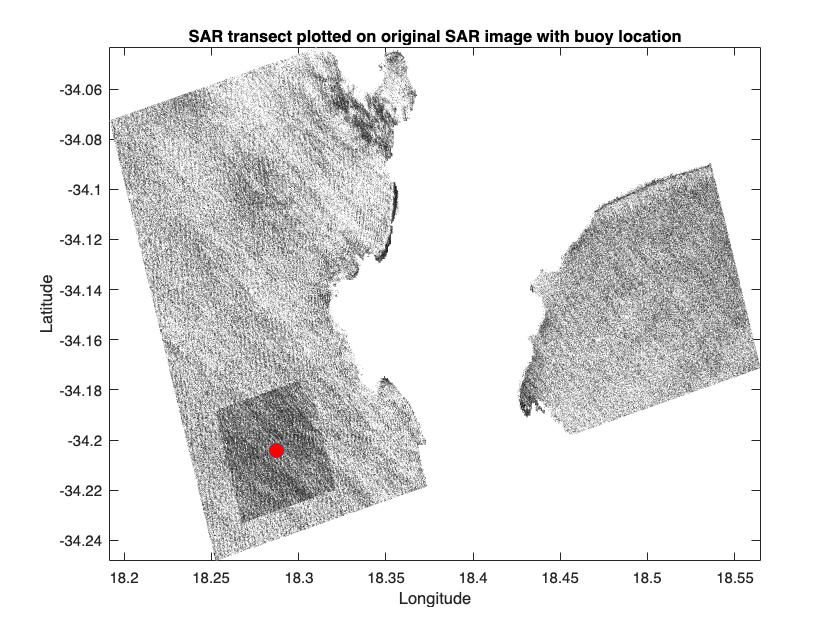

chosenTransect = 1;

if chosenTransect == 1
    latitude_of_interest = wave_buoy_lat;
    longitude_of_interest = wave_buoy_lon;

    clear sar_transect_data; clear sar_transect_lonGrid; clear sar_transect_latGrid; clear sar_transect_center_longitude; clear sar_transect_lon_indices; clear sar_transect_center_latitude; clear sar_transect_lat_indices; 

    [sar_transect_data,sar_transect_lonGrid,sar_transect_latGrid,sar_transect_center_longitude, sar_transect_lon_indices,sar_transect_center_latitude,sar_transect_lat_indices] = transectFunctions.transectFromSARImage(latitude_of_interest,longitude_of_interest,sar_latGrid,sar_lonGrid,sar_data, sar_transect_size);
    
    % Get the incidence angle at the center of the SAR transect.
    sar_transect_incidence_angle_degrees = sentinel.getIncidenceAngle(sar_transect_lat_indices, sar_transect_lon_indices);
    sentinel.TransectIncidenceAngles = table("open ocean", sar_transect_incidence_angle_degrees, 'VariableNames', {'Field', 'Value'});
    
    % Get the slant range at the center of the SAR transect
    % sar_transect_slant_range = sentinel.getSlantRange(sar_transect_lat_end_index(1),sar_transect_lat_start_index(1), sar_transect_lon_start_index(1),sar_transect_lon_end_index(1));
    sar_transect_slant_range = sentinel.getSlantRange(sar_transect_lat_indices, sar_transect_lon_indices);
    sentinel.TransectSlantRanges = table("open ocean", sar_transect_slant_range, 'VariableNames', {'Field', 'Value'});

    figure; plotFunctions.sarTransectOnSARImageWithBuoyLocation(sar_data(2000:4000,3000:6000), sar_latGrid(2000:4000, 3000:6000), sar_lonGrid(2000:4000, 3000:6000), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid,latitude_of_interest,longitude_of_interest, "SAR transect plotted on original SAR image with buoy location");

elseif chosenTransect ==2

    latitude_of_interest = latitude_of_interest_2;
    longitude_of_interest = longitude_of_interest_2;
    
    clear sar_transect_data; clear sar_transect_lonGrid; clear sar_transect_latGrid; clear sar_transect_center_longitude; clear sar_transect_lon_indices; clear sar_transect_center_latitude; clear sar_transect_lat_indices; 

    [sar_transect_data,sar_transect_lonGrid,sar_transect_latGrid,sar_transect_center_longitude, sar_transect_lon_indices,sar_transect_center_latitude,sar_transect_lat_indices] = transectFunctions.transectFromSARImage(latitude_of_interest,longitude_of_interest,sar_latGrid,sar_lonGrid,sar_data, sar_transect_size);
    
    % Get the incidence angle at the center of the SAR transect.
    sar_transect_incidence_angle_degrees = sentinel.getIncidenceAngle(sar_transect_lat_indices, sar_transect_lon_indices);
    sentinel.TransectIncidenceAngles = table("open ocean", sar_transect_incidence_angle_degrees, 'VariableNames', {'Field', 'Value'});
    
    % Get the slant range at the center of the SAR transect
    % sar_transect_slant_range = sentinel.getSlantRange(sar_transect_lat_end_index(1),sar_transect_lat_start_index(1), sar_transect_lon_start_index(1),sar_transect_lon_end_index(1));
    sar_transect_slant_range = sentinel.getSlantRange(sar_transect_lat_indices, sar_transect_lon_indices);
    sentinel.TransectSlantRanges = table("open ocean", sar_transect_slant_range, 'VariableNames', {'Field', 'Value'});

    figure; plotFunctions.sarTransectOnSARImageWithBuoyLocation(sar_data(2000:4000,3000:6000), sar_latGrid(2000:4000, 3000:6000), sar_lonGrid(2000:4000, 3000:6000), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid,latitude_of_interest,longitude_of_interest, "SAR transect plotted on original SAR image with buoy location");
 
elseif chosenTransect ==3
    latitude_of_interest = latitude_of_interest_3;
    longitude_of_interest = longitude_of_interest_3;
    
    clear sar_transect_data; clear sar_transect_lonGrid; clear sar_transect_latGrid; clear sar_transect_center_longitude; clear sar_transect_lon_indices; clear sar_transect_center_latitude; clear sar_transect_lat_indices; 

    [sar_transect_data,sar_transect_lonGrid,sar_transect_latGrid,sar_transect_center_longitude, sar_transect_lon_indices,sar_transect_center_latitude,sar_transect_lat_indices] = transectFunctions.transectFromSARImage(latitude_of_interest,longitude_of_interest,sar_latGrid,sar_lonGrid,sar_data, sar_transect_size);
    
    % Get the incidence angle at the center of the SAR transect.
    sar_transect_incidence_angle_degrees = sentinel.getIncidenceAngle(sar_transect_lat_indices, sar_transect_lon_indices);
    sentinel.TransectIncidenceAngles = table("open ocean", sar_transect_incidence_angle_degrees, 'VariableNames', {'Field', 'Value'});
    
    % Get the slant range at the center of the SAR transect
    % sar_transect_slant_range = sentinel.getSlantRange(sar_transect_lat_end_index(1),sar_transect_lat_start_index(1), sar_transect_lon_start_index(1),sar_transect_lon_end_index(1));
    sar_transect_slant_range = sentinel.getSlantRange(sar_transect_lat_indices, sar_transect_lon_indices);
    sentinel.TransectSlantRanges = table("open ocean", sar_transect_slant_range, 'VariableNames', {'Field', 'Value'});

    % figure; plotFunctions.sarTransectOnSARImageWithBuoyLocation(sar_data(2000:4000,3000:6000), sar_latGrid(2000:4000, 3000:6000), sar_lonGrid(2000:4000, 3000:6000), sar_transect_data, sar_transect_latGrid, sar_transect_lonGrid,latitude_of_interest,longitude_of_interest, "SAR transect plotted on original SAR image with buoy location");
end

Clear variables

% clear sar_data sar_lonGrid sar_latGrid;
clear latitude_of_interest_2 latitude_of_interest_3 longitude_of_interest_2 longitude_of_interest_3;
clear sar_transect_data_2 sar_transect_lonGrid_2 sar_transect_latGrid_2 sar_transect_center_longitude_2 sar_transect_lon_indices_2 sar_transect_center_latitude_2 sar_transect_lat_indices_2;
clear sar_transect_data_3 sar_transect_lonGrid_3 sar_transect_latGrid_3 sar_transect_center_longitude_3 sar_transect_lon_indices_3 sar_transect_center_latitude_3 sar_transect_lat_indices_3;

## 3 ERA5 Data

This is wave model data. We need to subdivide it to get the matching time, date, lattitudes and longitudes of our SAR data. The larger data then also needs to be sliced so that we can get the data matching the OO transect.

Finally, we need to calculate or use the mean wave direction so that are able to subdivide the SAR image into transects that flow into the ice.

### 3.1 Download

Get this from the CDS_ERA5_datahandling.mlx script. ****TO DO**: Make it adjustable so that the correct date and time data can be downloaded.

### 3.2 Import the data from the file

The data needs to be 'decoded' according to the ERA5 documentation:  [https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation](https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation)

%% Get Parameters of the complete
filepath = "/Users/tris/Documents/MSc/Data/Cape Point/CapePoint_ERA5-2Dws_20221014.nc";

% Store file info in MATLAB struct
% ncinfo_era5 = ncinfo(filepath);

era5 = ERA5(filepath);

% Get attributes
era5_longitudes = era5.getLongitude;
era5_latitudes = era5.getLatitude;
era5_time = era5.getTime;
% era5_d2fd_all_5dims = era5.getAllWaveSpectrumD2FD;

era5_freq_bins = era5.FrequencyBins;

era5_direction_bins_original_degrees = era5.DirectionBins;

### **3.3 Get the Wave spectrum at similar points to SAR data**

#### **3.3.1 Find the longitude and latitudes that are the closest to the SAR transect**

****TO DO: ADD evaluation for spectrum selected (if the closest point in the lat lon match is in the ice then check the next option).**

clear era5_d2fd; clear era5_lat; clear era5_lon; clear era5_datetime;
[era5_d2fd, era5_lat, era5_lon, era5_datetime] = era5.getSlicedWaveSpectrumD2Fd(sar_transect_center_latitude,sar_transect_center_longitude,sar_start_datetime);
era5_d2fd = era5_d2fd;

### 3.4 Adjust the Spectrum to match the SAR scene geometry

We need to then adjust the wave spectrum so that it is oriented the same as the SAR scene orientation

% % We need to rotate the wave spectrum so that it is aligned with the angle
% % at which the SAR data has been taken.
% % era5_direction_bins_degrees = era5.getDirectionsInSARGeometry(sar_azimuth_to_north_angle);
era5_direction_bins_degrees = era5_direction_bins_original_degrees;
% % NOTE HAD TO MOVE THE ADJUSTMENT TO AFTER THE INTERPOLATION OTHERWISE IT
% % AFFECTS THE CHARACTERISTICS --> SHOW THIS IN THE ERA5 TESTING AND WRITE
% % IN THE REPORT

Plot the data before and after being adjusted

% figure('Position', [100, 100, 800, 300]);
% subplot(1,2,1); plotFunctions.waveSpectrum2D(1,era5_d2fd',era5_freq_bins, era5_direction_bins_original_degrees, 0.3, "2-D Wave Spectrum, E(f,theta)");
% subplot(1,2,2);
%     % TO DO: FIX THIS METHOD
%     plotFunctions.waveSpectrumAdjustedToSAR(era5_d2fd', era5_freq_bins, era5_direction_bins_degrees, 0.3, "Adjusted to SAR scene geometry 2-D Wave Spectrum, E(f,theta)"); % ADD AZ AND RANGE AXIS LABELS

### **3.5 Plot the 2D wave spectra**

Note when working with the data: the dimensions are usually in the order lon lat time OR lon lat dir frq time. This can be checked by using ncinfo to get a structure of the file and then looking at the "Dimensions" field.

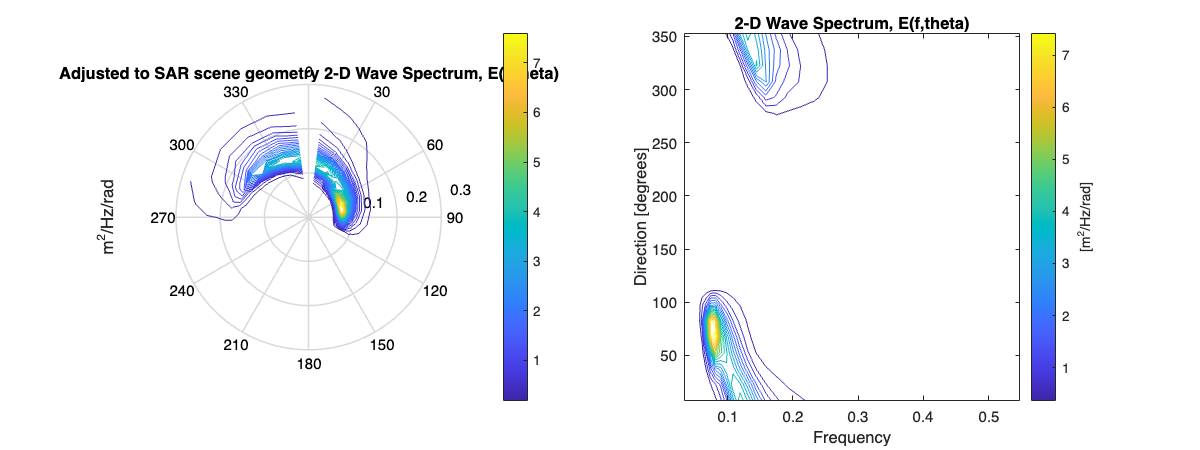

plotERA52Dspectrum = true;
if plotERA52Dspectrum
    % Plot the 2D spectra
    figure('Position', [100, 100, 800, 300]);
    subplot(1,2,1); plotFunctions.waveSpectrumAdjustedToSAR(era5_d2fd, era5_freq_bins, era5_direction_bins_degrees, 0.3, "Adjusted to SAR scene geometry 2-D Wave Spectrum, E(f,theta)"); % ADD AZ AND RANGE AXIS LABELS
    subplot(1,2,2);plotFunctions.waveSpectrum2D(0,era5_d2fd, era5_freq_bins, era5_direction_bins_original_degrees, 0.3, "2-D Wave Spectrum, E(f,theta)");
end

# Open Ocean H&H

## 1 First guess wave number spectrum

*This is derived from the Directional Wave Buoy (ERA5) Wave Spectrum data.*

- *You need to orient the wave spectrum to the SAR image angle. The SAR image is taken at a certain angle to the North (this angle can be found in the metadata). The ERA wave spectrum needs to be rotated so that it is inline with this. This is done earlier in the code when the data is imported by adding this angle to the direction bins of the ERA5 data. THis is a very important sstep as you need to orient the real spatial data in temrs of the SAR geometry. This angle can also clearly be seen when viewing the SAR image plots (the plot where the longitude and latittude axes are added vs the plot where they are not).*

- *Then we need to calculate the ****wave number spectrum**** from the E(f, theta). Note here that the ERA data is given in E(f,theta) but the Holthuijsen formula requires E(w,theta). To obtain this we need E(w, theta) = 2 pi E(f, theta). Holthuijsen is used as the reference for this BUT also investigate the Dynamics and Modeling of Ocean Waves (recommended by Giacomo)      *

- **Note: The wave number spectrum is the projection of the wave spectrum (f,theta) into the wavenumber (kx,ky) domain.** **"**Where the wave spectrum considers the sea as a function of space and time, η(x, y, t), the ocean can also be considered as a function of space at a single moment in time. This idea is useful for remote sensing applications."  "The wave-number spectrum, E(kx,ky) is useful for remote sensing applications, and the frequency-direction spectrum, E(f,θ), is used for wave models"  (Ryan 4022). pg 20-21

- This needs to be a plot of the ERA5 d2fd data on a kx ky grid. See the comments below but need to look at how it is 

- done in Holthuijsen.

- Make the plot and then compare to the HH paper. Plot next to the f theta plot to see the difference and the translation.

### 1.0 Interpolate Wave Spectrum

era5_direction_bins_degrees = era5_direction_bins_original_degrees;

interp_size = 128;
[interp_era5_d2fd, interp_era5_freq_bins, interp_era5_direction_bins_degrees] = waveLibrary.interpolateWaveSpectrum(interp_size, era5_freq_bins,era5_direction_bins_degrees,era5_d2fd,"ERA5");

% figure('Position', [200, 200, 1200, 400]);
% subplot(1,2,1); plotFunctions.waveSpectrum2D(1,org_era5_d2fd', org_era5_freq_bins, org_era5_direction_bins_degrees, 0.3, "Org 2-D Wave Spectrum, E(f,theta)");
% subplot(1,2,2); plotFunctions.waveSpectrum2D(1,era5_d2fd', era5_freq_bins, era5_direction_bins_degrees, 0.3, "Interp 2-D Wave Spectrum, E(f,theta)");
[Hs_derived,Tm_derived,direction_derived,~] = ...
        waveLibrary().calculateSpectrumCharacteristics(era5_direction_bins_degrees.*(pi/180),era5_freq_bins,era5_d2fd)

Hs_derived = 3.1245

Tm_derived = 6.9475

direction_derived = 15.8428


[Hs_derived_interp,Tm_derived_interp,direction_derived_interp,~] = ...
        waveLibrary().calculateSpectrumCharacteristics(interp_era5_direction_bins_degrees.*(pi/180),interp_era5_freq_bins,interp_era5_d2fd)

Hs_derived_interp = 3.1207

Tm_derived_interp = 6.9529

direction_derived_interp = 15.9310

### 1.0.1 Adjust the Spectrum to match the SAR scene geometry

We need to then adjust the wave spectrum so that it is oriented the same as the SAR scene orientation. MUST BE DONE AFTER INTERPOLATION NOT THE OTHER WAY AROUND.

% % We need to rotate the wave spectrum so that it is aligned with the angle
% % at which the SAR data has been taken.
adjusted_direction_bins_degrees = handh.getDirectionsInSARGeometry(interp_era5_direction_bins_degrees,sar_azimuth_to_north_angle);
% % NOTE HAD TO MOVE THE ADJUSTMENT TO AFTER THE INTERPOLATION OTHERWISE IT
% % AFFECTS THE CHARACTERISTICS --> SHOW THIS IN THE ERA5 TESTING AND WRITE
% % IN THE REPORT

Plot the data before and after being adjusted

% figure('Position', [100, 100, 800, 300]);
% subplot(1,2,1); plotFunctions.waveSpectrum2D(1,era5_d2fd',era5_freq_bins, era5_direction_bins_original_degrees, 0.3, "2-D Wave Spectrum, E(f,theta)");
% subplot(1,2,2);
%     % TO DO: FIX THIS METHOD
%     plotFunctions.waveSpectrumAdjustedToSAR(e

[Hs_derived_interp,Tm_derived_interp,direction_derived_interp,~] = ...
        waveLibrary().calculateSpectrumCharacteristics(interp_era5_direction_bins_degrees.*(pi/180),interp_era5_freq_bins,interp_era5_d2fd)

Hs_derived_interp = 3.1207

Tm_derived_interp = 6.9529

direction_derived_interp = 15.9310

### 1.1 Parameter Calculations / Instantiation

gravity = 9.81;

### **1.2 Wave Number Spectrum Function**

**Holthuisen** states that "*"Remote-sensing *and numerical wave models can estimate the full two-dimensional spectrum, usually the wave-number spectrum *E *(*k x *, *k y *)" [pg.52 Holthuijsen]. So we now need to calculate the wave number spectrum

interp_era5_omega = (2 * pi) .* interp_era5_freq_bins; % Angular velocity, omega = 2pi * frequency; also calculated as era5_omega = sqrt(gravity .* era5_k)
 
interp_era5_k = (interp_era5_omega).^2 ./ gravity; % from deep water approximation of omega = sqrt(gk), [Eq.5.4.18 Holthuijsen]
% [interp_E_kx_ky, Jacobian_kx_ky, interp_kx_matrix,interp_ky_matrix] = waveLibrary().waveNumberSpectrum(interp_S_2D,interp_w,interp_k,interp_theta_degrees.*(pi/180));
[interp_wave_number_spectrum, Jacobian, interp_kx_matrix,interp_ky_matrix] = waveLibrary.waveNumberSpectrum(interp_era5_d2fd,interp_era5_omega,interp_era5_k, adjusted_direction_bins_degrees.*(pi/180),direction_derived_interp,sar_azimuth_to_north_angle);

#### 1.2.1 Plot Wave Number Spectra, E(k) with E(f,theta)

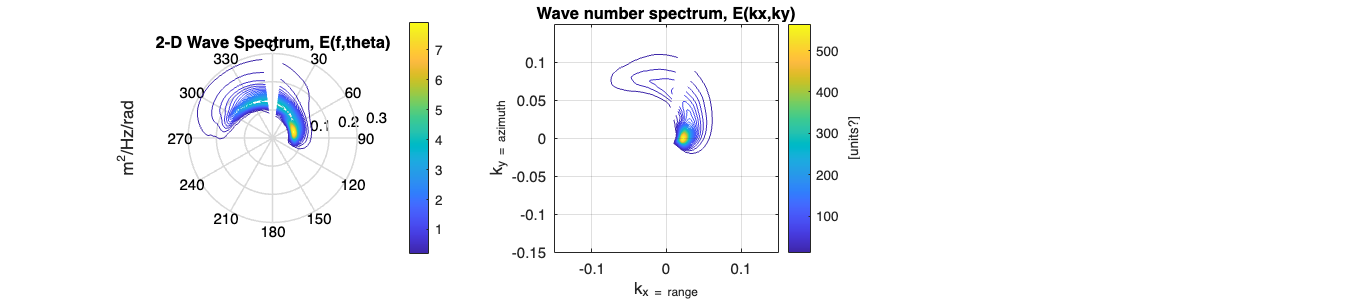

figure('Position', [0, 0, 900, 200]);
subplot(1,3,1);
    plotFunctions.waveSpectrum2D(1,interp_era5_d2fd, interp_era5_freq_bins, interp_era5_direction_bins_degrees, 0.3, "2-D Wave Spectrum, E(f,theta)");
subplot(1,3,2);
    plotLibrary().waveNumberSpectrum(interp_wave_number_spectrum, ...
            interp_kx_matrix, interp_ky_matrix, "Wave number spectrum, E(kx,ky)"); xlim([-0.15 0.15]); ylim([-0.15 0.15]); grid on;

### 1.4 First Guess Wave Number Spectra Variables

These final variables are redundant but helpful for now in the process of understanding things.

first_guess_wave_number_spectrum = interp_wave_number_spectrum;
first_guess_kx_range = interp_kx_matrix;
first_guess_ky_azimuth = interp_ky_matrix;



% interp_era5_k = linspace(min(interp_era5_k),max(interp_era5_k),128);
% 
% % 
% % 
% % angle = mean_wave_dir + abs(azimuth_angle);
% %     lin_k = linspace(min(k),max(k),128);
% %     lin_kx_matrix = lin_k .* sind(angle); % [rad/m] [Eq.3.5.19b Holthuijsen]
% %     lin_ky_matrix = lin_k .* cosd(angle); % [rad/m] [Eq.3.5.19b Holthuijsen]
% 
% % [first_guess_kx_range,first_guess_ky_azimuth,first_guess_wave_number_spectrum] = waveLibrary.lineariseKxandKyMatrices(interp_kx_matrix,interp_ky_matrix,interp_wave_number_spectrum);
% % % nanVals = isnan(first_guess_wave_number_spectrum);
% % % first_guess_wave_number_spectrum(nanVals) = 0;
% % scale = (interp_wave_number_spectrum./ first_guess_wave_number_spectrum);
% % scale(isnan(scale)) = 0;
% % first_guess_wave_number_spectrum =  median(scale(:)) .* first_guess_wave_number_spectrum;
% first_guess_kx_range = interp_era5_k .* cosd(handh.getDirectionsInSARGeometry(direction_derived_interp,sar_azimuth_to_north_angle));
% % first_guess_kx_range = linspace(min(first_guess_kx_range),max(first_guess_kx_range),128/2);
% % first_guess_kx_range = [-fliplr(first_guess_kx_range) first_guess_kx_range];
% first_guess_kx_range = ones(128,128).*first_guess_kx_range;
% % first_guess_ky_azimuth = interp_ky_matrix;
% first_guess_ky_azimuth = interp_era5_k .* sind(handh.getDirectionsInSARGeometry(direction_derived_interp,sar_azimuth_to_north_angle));
% % first_guess_ky_azimuth = linspace(min(first_guess_ky_azimuth),max(first_guess_ky_azimuth),128/2);
% % first_guess_ky_azimuth = [-fliplr(first_guess_ky_azimuth) first_guess_ky_azimuth]';
% first_guess_ky_azimuth = ones(128,128).*first_guess_ky_azimuth';
% % first_guess_kx_range = linspace(min(abs(interp_kx_matrix(:))),max(abs(interp_kx_matrix(:))),128/2);
% % first_guess_kx_range = [-1*fliplr(first_guess_kx_range) first_guess_kx_range]; % Necessary to remove k=0 as this does not exist.
% % 
% % first_guess_ky_azimuth = linspace(min(abs(interp_ky_matrix(:))),max(abs(interp_ky_matrix(:))),128/2);
% % first_guess_ky_azimuth = [-1*fliplr(first_guess_ky_azimuth) first_guess_ky_azimuth]; % Necessary to remove k=0 as this does not exist.
% % 
% 

first_guess_k = sqrt(interp_kx_matrix.^2 + interp_ky_matrix.^2);
% first_guess_k = sqrt(first_guess_kx_range.^2 + first_guess_ky_azimuth.^2);
% first_guess_k = interp_era5_k;
% first_guess_k = linspace(min(abs(first_guess_k(:))),max(abs(first_guess_k(:))),128/2);
% first_guess_k = [fliplr(first_guess_k) first_guess_k];


first_guess_omega = sqrt(gravity .* abs(first_guess_k)); % [Engen, 1995]

[final_d2fd,inverse_Jacobian] = waveLibrary.waveSpectrum(first_guess_wave_number_spectrum, first_guess_omega, first_guess_k);
% figure; contour(interp_era5_freq_bins,interp_era5_direction_bins_degrees,final_d2fd); hold on; contour(interp_era5_freq_bins,interp_era5_direction_bins_degrees,interp_wave_number_spectrum)
[Hs_derived_interp,Tm_derived_interp,direction_derived_interp_adj,~] = ...
        waveLibrary().calculateSpectrumCharacteristics(adjusted_direction_bins_degrees.*(pi/180),interp_era5_freq_bins,final_d2fd)

Hs_derived_interp = 3.1207

Tm_derived_interp = 6.9529

direction_derived_interp_adj = 31.5831

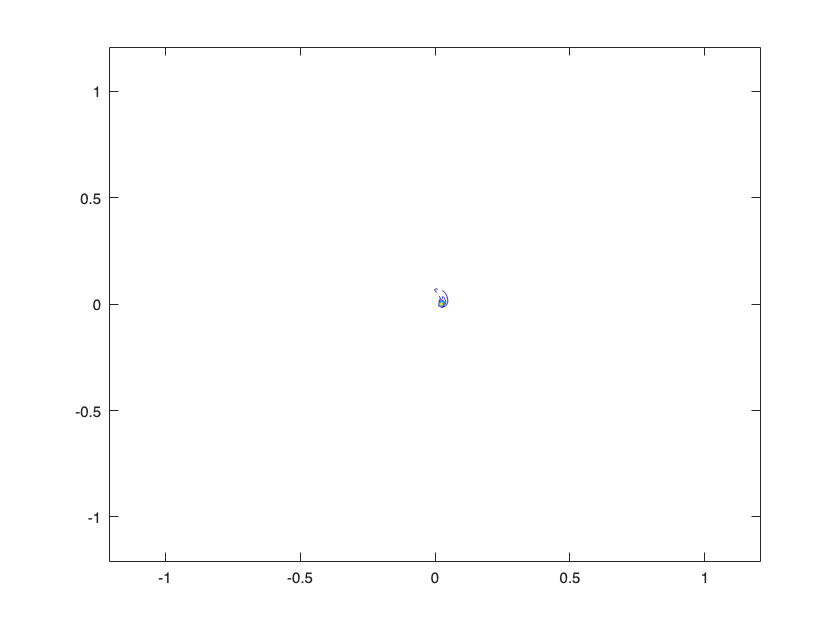


% clear interp_E_kx_ky; clear interp_kx_matrix; clear interp_ky_matrix;

% figure('Position', [0, 0, 1500, 300]);
%     subplot(1,4,1);
%         contour(first_guess_kx_range,first_guess_ky_azimuth,first_guess_wave_number_spectrum)
%     subplot(1,4,2);
% 
%     subplot(1,4,3);
% 
%     subplot(1,4,4);

figure;contour(first_guess_kx_range,first_guess_ky_azimuth,first_guess_wave_number_spectrum)

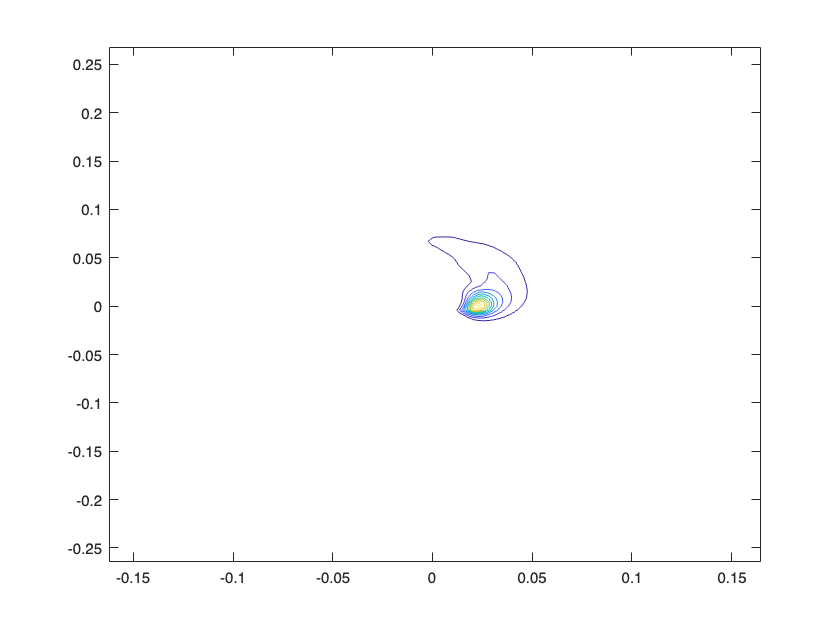

% dk = 2 * pi/(128 * sar_dy_azimuth);
% kmin = -pi/sar_dy_azimuth + dk;
% kmax = pi/sar_dy_azimuth;
% k_giacomo = kmin:dk:kmax;
% figure; plot(k_giacomo);
% k_mine = linspace(min(interp_era5_k),max(interp_era5_k),128/2);
% k_mine = [-fliplr(k_mine) k_mine];
% figure; plot(k_mine);
first_guess_k = k_giacomo;
first_guess_omega = sqrt(gravity .* abs(first_guess_k)); % [Engen, 1995]
% first_guess_kx_range = interp_era5_k .* sind(handh.getDirectionsInSARGeometry(direction_derived_interp,sar_azimuth_to_north_angle));
% first_guess_ky_azimuth = interp_era5_k .* cosd(handh.getDirectionsInSARGeometry(direction_derived_interp,sar_azimuth_to_north_angle));

mean_theta = direction_derived_interp +abs(sar_azimuth_to_north_angle);
first_guess_kx_range = first_guess_k .* sind(mean_theta);
first_guess_ky_azimuth = first_guess_k .* cosd(mean_theta);

[xq,yq] = meshgrid(first_guess_kx_range, first_guess_ky_azimuth);
first_guess_kx_range = xq;
first_guess_ky_azimuth = yq;

first_guess_wave_number_spectrum = griddata(interp_kx_matrix,interp_ky_matrix,interp_wave_number_spectrum,first_guess_kx_range,first_guess_ky_azimuth);

figure; contour(first_guess_kx_range,first_guess_ky_azimuth,first_guess_wave_number_spectrum);

## 2 First Guess SAR Spectrum - H&H's Sar Imaging of Ocean Waves *pg.2*

*This is derived from the First Guess Wave Number Spectrum.*

- Figure our where in the paper this is and then compute the SAR spectrum from the ERA 5 first guess wave spectrum in step 1

- Plot these on kx ky grid - might need to limit the Fmax value as shown in Fig 3 of HH91 --> Fmax is not limited, it is filtered

### 2.0 Generate SAR Spectrum Function

This calls the function that performs all the steps in the rest of this section.

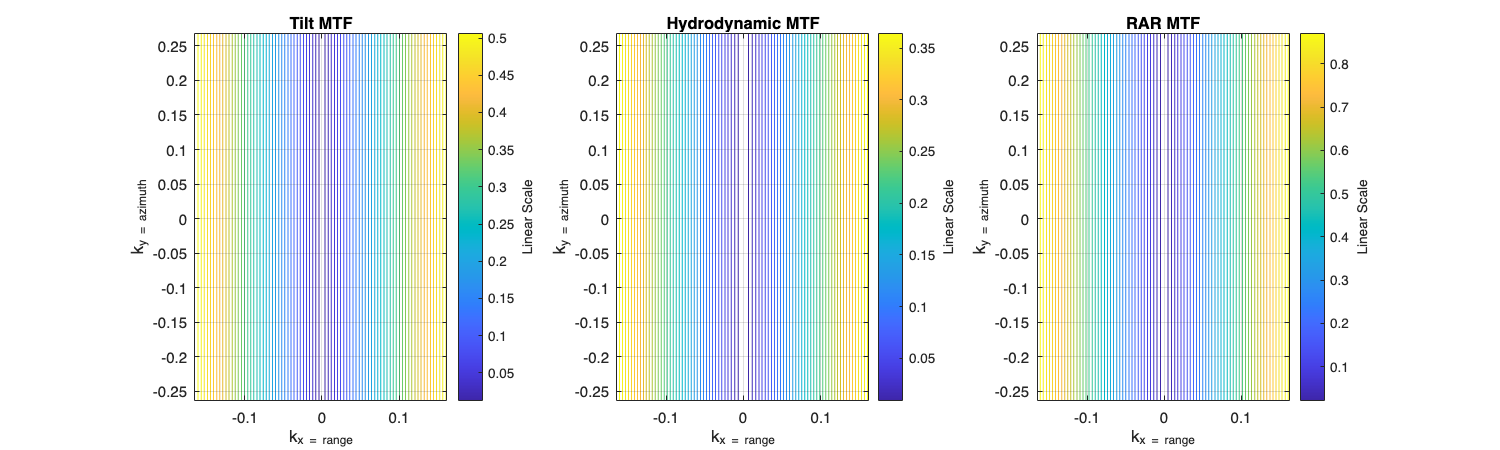

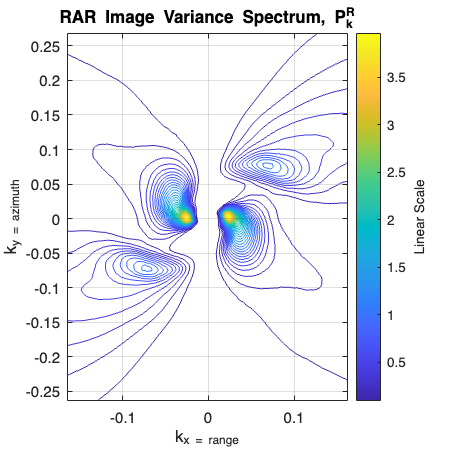

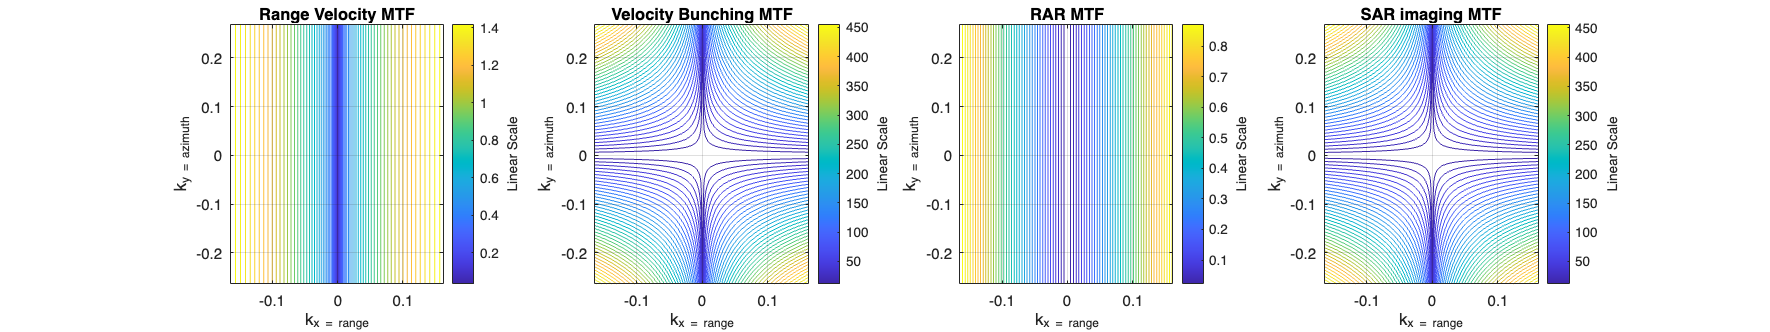

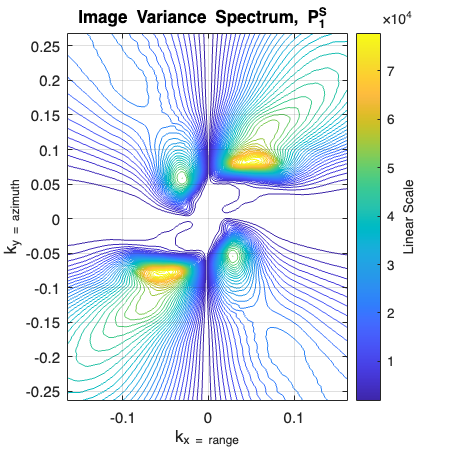

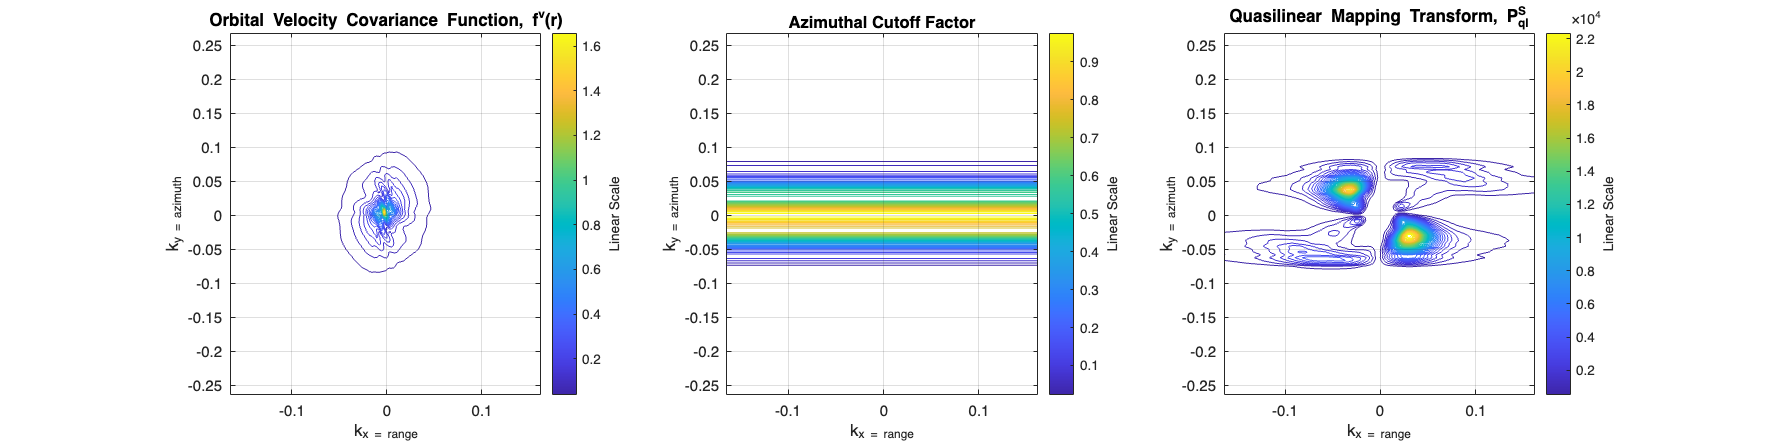

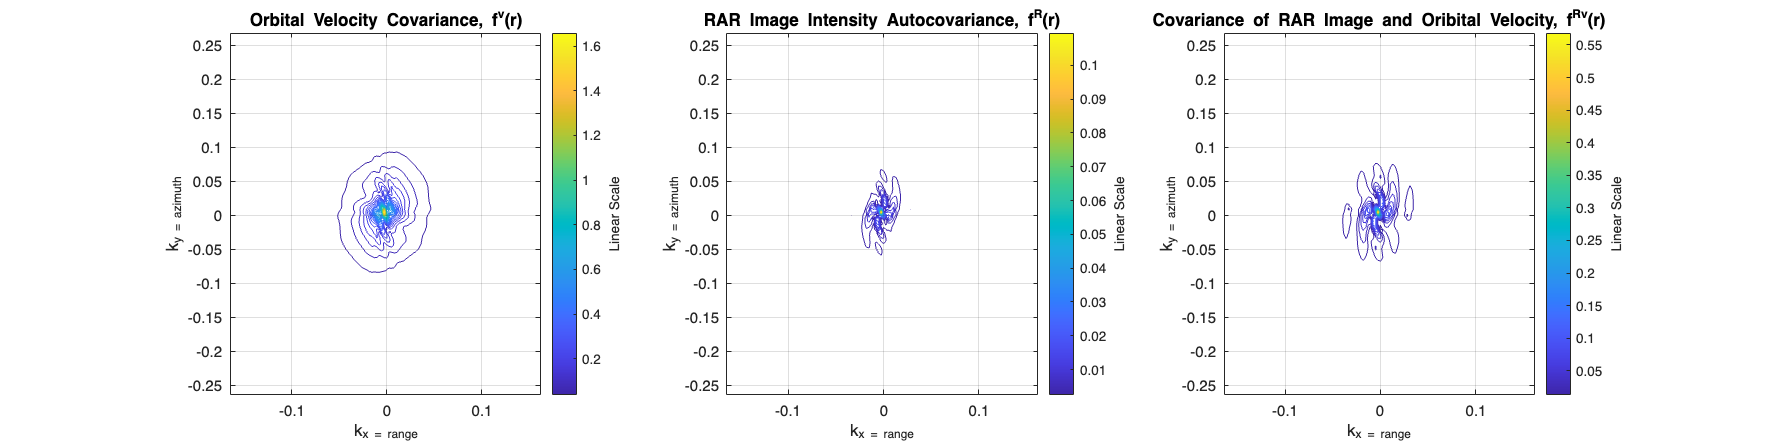

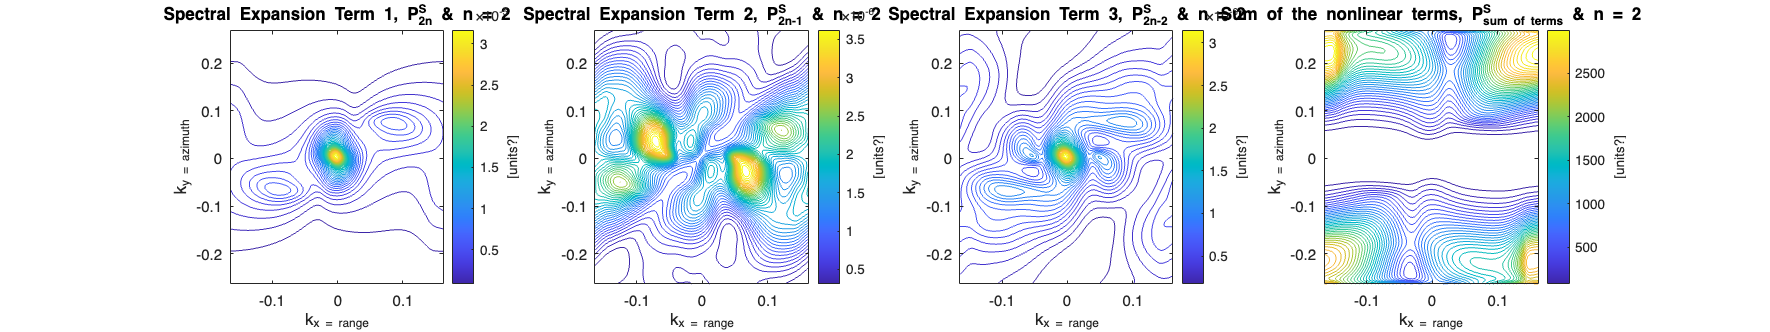

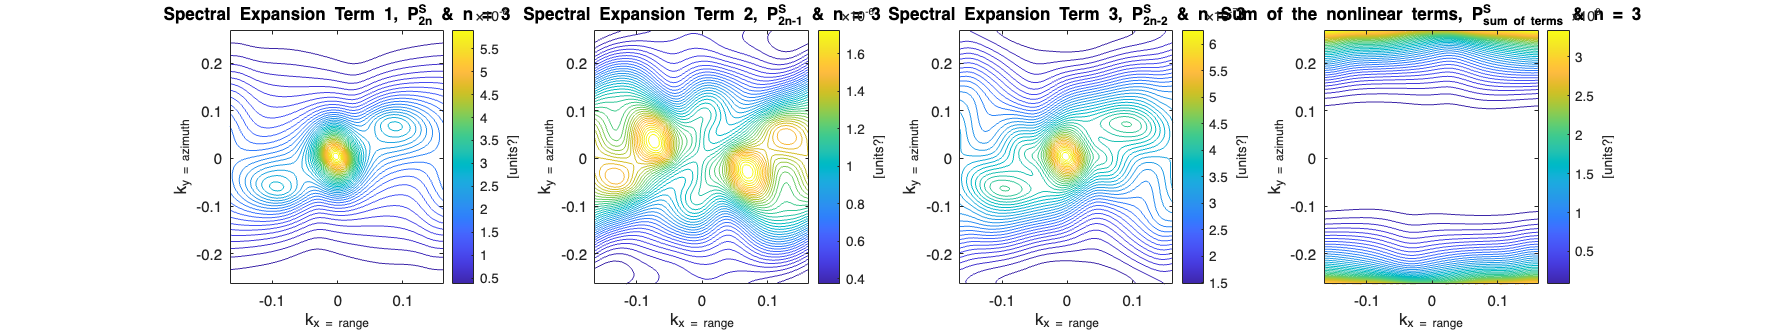

% Run the function
nonlinearity_order = 3;
[first_guess_sar_spectrum, TS_k, Tv_k, sar_beta, xi_sqr] = handh.generateSARSpectrumFromWaveNumberSpectrum(sentinel, 1, 1, nonlinearity_order, sar_sub_transect_size, first_guess_kx_range, first_guess_ky_azimuth, first_guess_omega, first_guess_k,first_guess_wave_number_spectrum);

This code is a sanity check to compare the wavelength of the wave spectrum to that of the SAR spectrum. ****TODO**: move this somewhere else

% ps_k_nl = ps_k_nl / max(ps_k_nl(:)) * max(cross_spec(:));

% [temp1, temp2] = find(interp_E_kx_ky==max(interp_E_kx_ky(:)));
% k0 = first_guess_k(temp1,temp2);
% peak_wave_length_Ek = 2*pi/k0;

## 3 Observed SAR spectrum

- Subdivide the 512x512 transect into 16 128x128 sub transects

- For each sub transect: filter, normalise, fft

- Take the average of these sub transects

- Need to filter out the low frequencies using butterworth filter applied to covariance function and then ifft back to the spectrum

% Without filtering
[observed_sar_spectrum_without_butterworth_gaussian] = observedSARSpectrum(sar_transect_data, sar_transect_size, sar_sub_transect_size, sar_dx_range, first_guess_k, 1, 1, -1,first_guess_sar_spectrum);

% Using the Butterworth filter
cutoff = 450; % This is dependent on the sea state and used to remove the low frequencies. Maybe see if 2 * swell will work.
[observed_sar_spectrum_with_butterworth_without_gaussian] = observedSARSpectrum(sar_transect_data, sar_transect_size, sar_sub_transect_size, sar_dx_range, first_guess_k, 1, 1, cutoff,first_guess_sar_spectrum);

% Using the Gaussian smoothing filter
size_of_filter_window = 5; % The number of elements = dim_filt + 1
width_of_gaussian_lobe = 2; % width_of_gaussian_lobe: Controls the spread of the Gaussian. A larger width means the Gaussian will be wider and smoother.
[observed_sar_spectrum] = observedSARSpectrum(sar_transect_data, sar_transect_size, sar_sub_transect_size, sar_dx_range, first_guess_k, size_of_filter_window, width_of_gaussian_lobe, cutoff,first_guess_sar_spectrum);

% figure('Position', [0, 0, 1200, 600]);
%     subplot(2,3,1); plotFunctions.generalSpectrumPlots(0,observed_sar_spectrum_without_butterworth_gaussian, first_guess_kx_range, first_guess_ky_azimuth, "SAR Spectrum, P^S_{obs}: without Butterworth cutoff and Gaussian Filter ");
%     subplot(2,3,2); plotFunctions.generalSpectrumPlots(0,observed_sar_spectrum_with_butterworth_without_gaussian, first_guess_kx_range, first_guess_ky_azimuth, "SAR Spectrum, P^S_{obs}: with Butterworth cutoff = ?, without Gausian filter ");
%     subplot(2,3,3); plotFunctions.generalSpectrumPlots(0,observed_sar_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "SAR Spectrum, P^S_{obs}: with Butterworth cutoff = ? and Gausian filter dim = 5, width = 2 ");
%     subplot(2,3,4); plotFunctions.generalSpectrumPlots(1,observed_sar_spectrum_without_butterworth_gaussian, first_guess_kx_range, first_guess_ky_azimuth, "SAR Spectrum, P^S_{obs}: without Butterworth cutoff and Gaussian Filter ");
%     subplot(2,3,5); plotFunctions.generalSpectrumPlots(1,observed_sar_spectrum_with_butterworth_without_gaussian, first_guess_kx_range, first_guess_ky_azimuth, "SAR Spectrum, P^S_{obs}: with Butterworth cutoff = ?, without Gausian filter ");
%     subplot(2,3,6); plotFunctions.generalSpectrumPlots(1,observed_sar_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "SAR Spectrum, P^S_{obs}: with Butterworth cutoff = ? and Gausian filter dim = 5, width = 2 ");

### Plot the observed and simulated spectra together

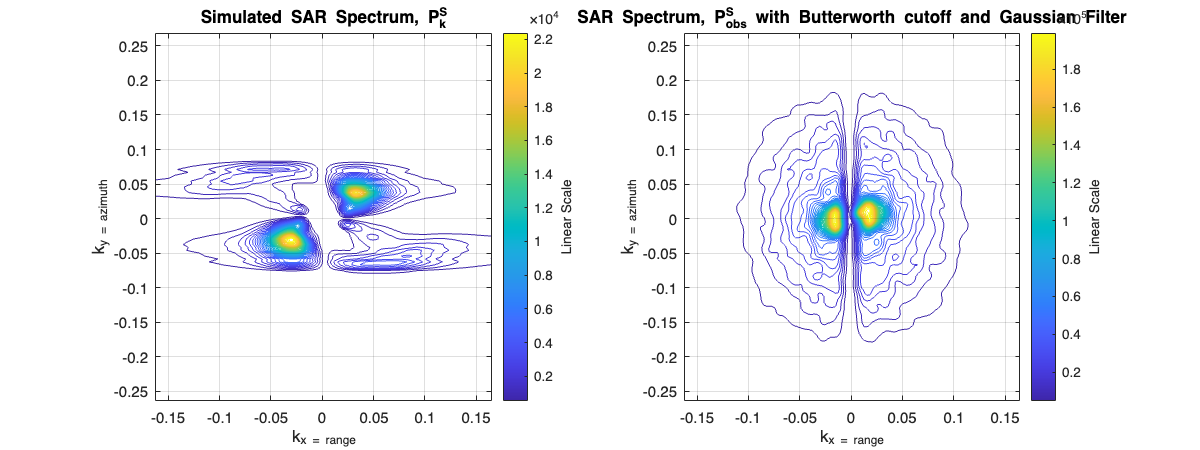

figure('Position', [0, 0, 800, 300]);
    subplot(1,2,1); plotFunctions.generalSpectrumPlots(0,first_guess_sar_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "Simulated SAR Spectrum, P^S_k");
    subplot(1,2,2); plotFunctions().generalSpectrumPlots(0,observed_sar_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "SAR Spectrum, P^S_{obs} with Butterworth cutoff and Gaussian Filter");

## 4 Inversion

applyStepZero = false;

### 4.0 General variables

transect_number = 1; % This will mainly be used when looping through all transects in the ice part of the pipeline

nonlinearity_order = 3;
inversion_iterations = 10;
F_era5_k = first_guess_wave_number_spectrum;
P_era5_k = first_guess_sar_spectrum;

***PROBLEM: (NOT IN SENTINEL)***

***This seems to be a bug... not sure where it is caused.***

% ky = flipud(ky);

The above additional step is required to ensure that the values returned in the cost function are positive. When this step is used, kx and ky are both linearly ascending rather than ky ascending and kx descending (seen when plotting the variables). When they are opposite, the integration in the cost function equations result in a negative output rather than a positive value. Therefore, the kx variable is flipped so that it is identical to ky. 

My only concern here is that the kx and ky matrices do not look the same because we are dealing with a right-looking SAR. As per the definition in H&H, for a right looking SAR ky = -1 ky. That is why kx and ky are not identical. Does making them identical here effect anything?

### 4.1 Step Zero

- "Step zero" as Giacomo calls it

- Page 10,723 of H&H 1991

if  applyStepZero
    kx = first_guess_kx_range(1,:); % This is required for integration
    ky = first_guess_ky_azimuth(:,1); % This is required for integration
    [J_step0, S_new, P_new, energy_scale, new_kx_0,new_ky_0,rot_angle, mag_scale, Tv_k, sar_beta, TS_k,xi_sqr] = inversionStep0(nonlinearity_order, 0,transect_number, observed_sar_spectrum, first_guess_wave_number_spectrum,first_guess_kx_range,first_guess_ky_azimuth,first_guess_omega,first_guess_k,sar_sub_transect_size, sentinel, handh);
    
    % Plot the outputs
    figure('Position', [0, 0, 1200, 600]);
        subplot(2,4,1); plotFunctions.generalSpectrumPlots(0,observed_sar_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "Observed SAR spectrum");
        subplot(2,4,2); plotFunctions.generalSpectrumPlots(0,first_guess_sar_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "First guess SAR spectrum");
        subplot(2,4,3); plotFunctions.generalSpectrumPlots(0,P_new, new_kx_0, new_ky_0, "New SAR Spectrum");
        subplot(2,4,4); 
            clear temp; temp(:,:) = J_step0(:,1,:); surf(temp); view(2);
            title("Minimisation Values"); ylabel("Wave Number Scaling Factor"); xlabel("Rotation angle (degrees)"); 
            c = colorbar(); c.Label.String = 'Minimisation magnitude';
        subplot(2,4,6); plotFunctions.generalSpectrumPlots(0,first_guess_wave_number_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "First guess wave number spectrum");
        subplot(2,4,7); plotFunctions.generalSpectrumPlots(0,S_new, first_guess_kx_range, first_guess_ky_azimuth, "New wave number Spectrum");
    
    % Update the variables to the new values
    F_era5_k = S_new;
    first_guess_kx_range = new_kx_0;
    first_guess_ky_azimuth = new_ky_0 ;
    first_guess_k = sqrt(first_guess_ky_azimuth.^2 +first_guess_kx_range.^2);
    first_guess_omega = sqrt(9.81 * first_guess_k);
end

### 4.2 Inversion: Eq 62, 63 & 69   

[J_eq_62,P_best_eq62,F_best_eq62,J_eq_63,P_best_eq63,F_best_eq63,J_eq_69,P_best_eq69,F_best_eq69] = inversionHH(inversion_iterations, nonlinearity_order, sentinel, handh, 0, observed_sar_spectrum, F_era5_k, transect_number, sar_sub_transect_size, first_guess_kx_range, first_guess_ky_azimuth, first_guess_omega, first_guess_k , Tv_k, sar_beta, TS_k);

Eq62: iteration 1
Eq63: iteration 1
Eq96: iteration 1
Eq62: iteration 2
Eq63: iteration 2
Eq62: iteration 3
Eq63: iteration 3
Eq62: iteration 4
Eq63: iteration 4
Eq62: iteration 5
Eq63: iteration 5
Eq62: iteration 6
Eq63: iteration 6
Eq62: iteration 7
Eq63: iteration 7
Eq62: iteration 8
Eq63: iteration 8
Eq62: iteration 9
Eq63: iteration 9
Eq62: iteration 10
Eq63: iteration 10


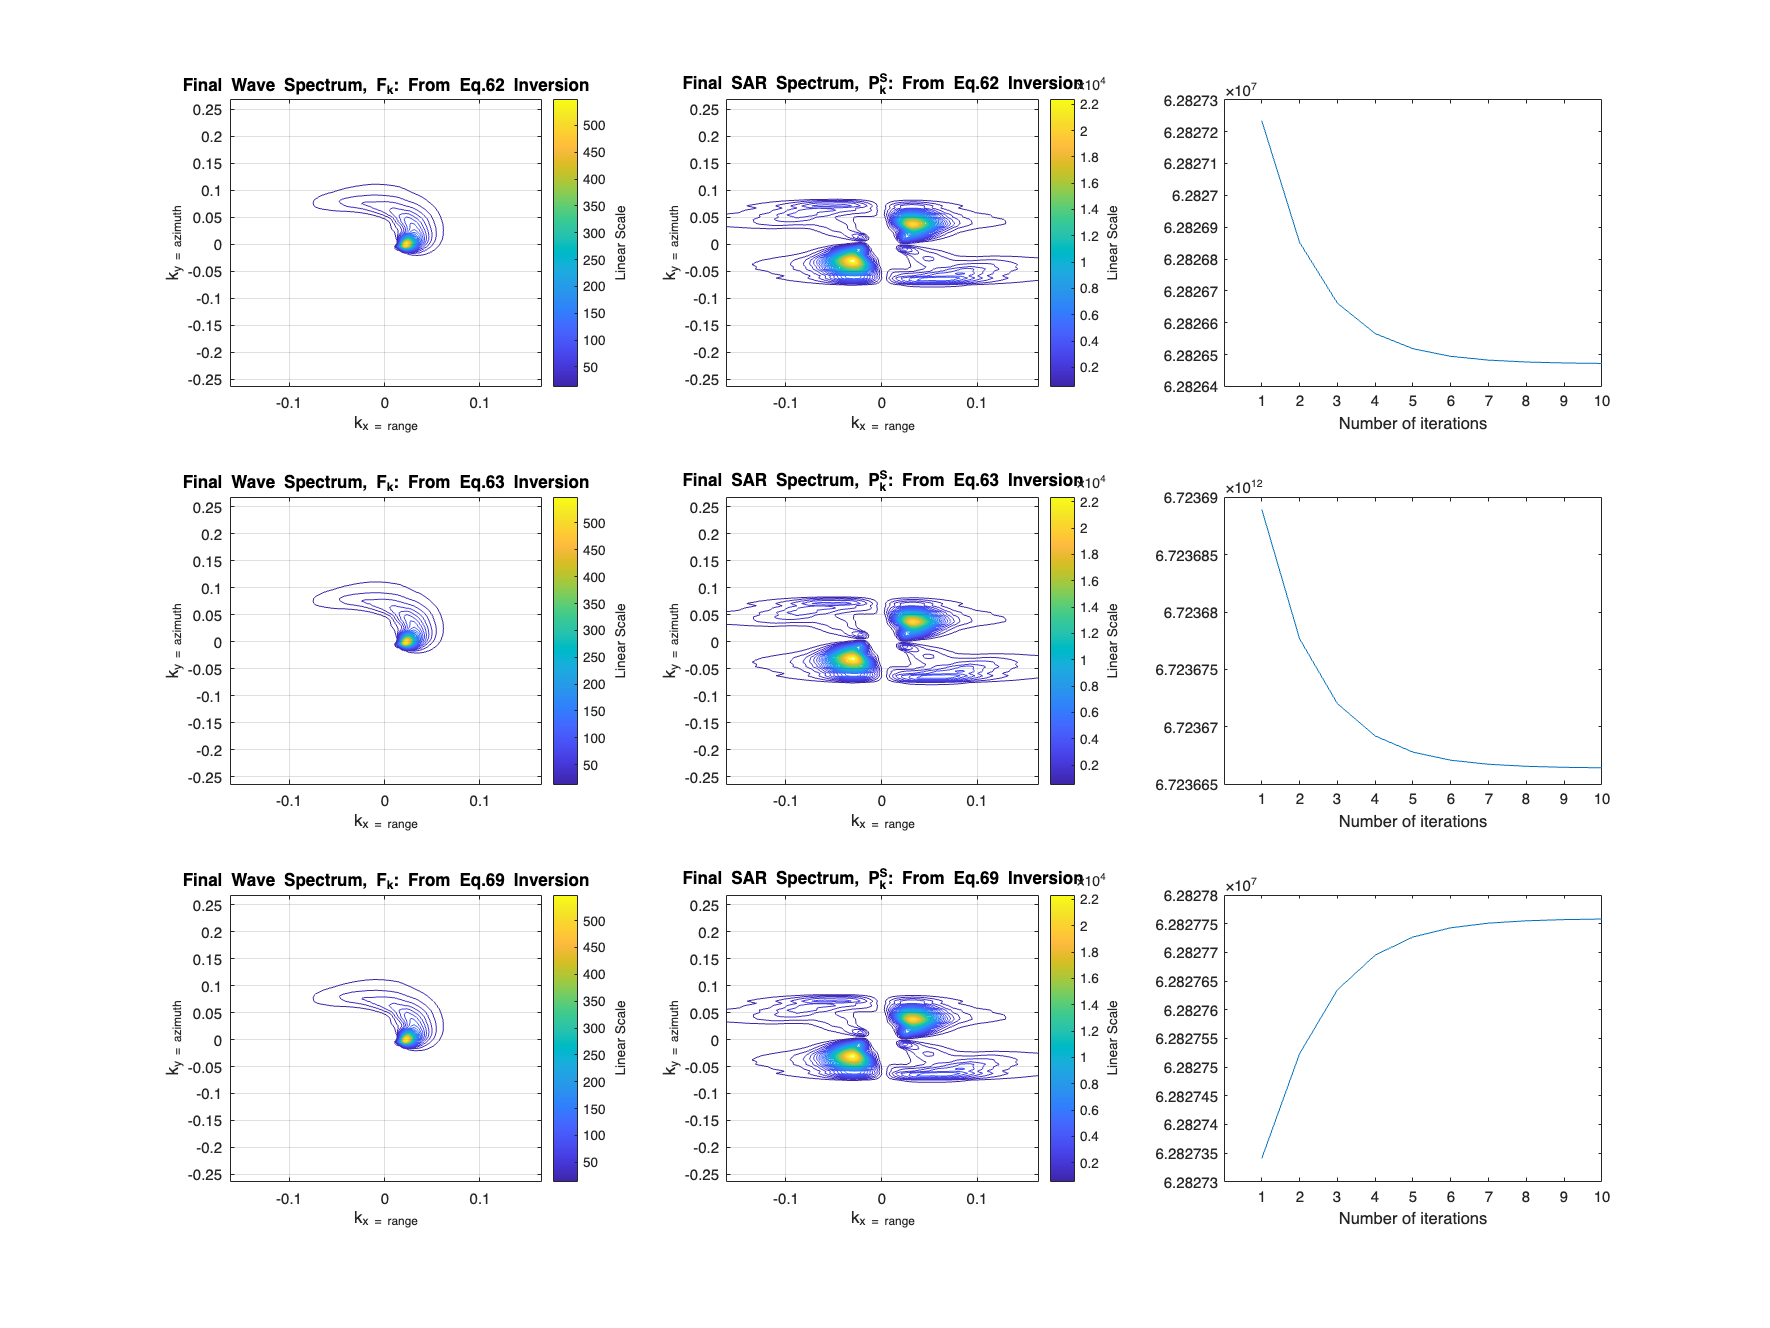

%TO DO: ADD MARKER TO SHOW WHICH ITERATION WAS CHOSEN
figure('Position', [0, 0, 1200, 900]);
    subplot(3,3,1); plotFunctions.generalSpectrumPlots(0,F_best_eq62, first_guess_kx_range, first_guess_ky_azimuth, "Final Wave Spectrum, F_k: From Eq.62 Inversion");
    subplot(3,3,2); plotFunctions.generalSpectrumPlots(0,P_best_eq62, first_guess_kx_range, first_guess_ky_azimuth, "Final SAR Spectrum, P^S_{k}: From Eq.62 Inversion");
    subplot(3,3,3); 
        plot(J_eq_62); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");
    subplot(3,3,4); plotFunctions.generalSpectrumPlots(0,F_best_eq63, first_guess_kx_range, first_guess_ky_azimuth, "Final Wave Spectrum, F_k: From Eq.63 Inversion");
    subplot(3,3,5); plotFunctions.generalSpectrumPlots(0,P_best_eq63, first_guess_kx_range, first_guess_ky_azimuth, "Final SAR Spectrum, P^S_{k}: From Eq.63 Inversion");
    subplot(3,3,6);
        plot(J_eq_63); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");
    subplot(3,3,7); plotFunctions.generalSpectrumPlots(0,F_best_eq69, first_guess_kx_range, first_guess_ky_azimuth, "Final Wave Spectrum, F_k: From Eq.69 Inversion");    
    subplot(3,3,8); plotFunctions.generalSpectrumPlots(0,P_best_eq69, first_guess_kx_range, first_guess_ky_azimuth, "Final SAR Spectrum, P^S_{k}: From Eq.69 Inversion");    
    subplot(3,3,9); 
        plot(J_eq_69); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");

### 4.3 Giacomo's Inversion

[F_best_giacomo_eps, P_best_giacomo_eps, eps, F_best_giacomo_J, P_best_giacomo_J, J] = inversionGiacomo(inversion_iterations, nonlinearity_order, F_era5_k, observed_sar_spectrum, TS_k, first_guess_ky_azimuth ,first_guess_kx_range,xi_sqr, first_guess_omega, sentinel,first_guess_k,transect_number,sar_sub_transect_size, handh);

Index in position 1 exceeds array bounds. Index must not exceed 1.

Error in inversionGiacomo (line 10)
    k0 = first_guess_k(temp1,temp2);


figure('Position', [100, 100, 1200, 600]);
    subplot(2,3,1); plotFunctions.generalSpectrumPlots(0,F_best_giacomo_J, first_guess_kx_range, first_guess_ky_azimuth, "Final Wave Spectrum, F_k: From Giacomo J Inversion");    
    subplot(2,3,2); plotFunctions.generalSpectrumPlots(0,P_best_giacomo_J, first_guess_kx_range, first_guess_ky_azimuth, "Final SAR Spectrum, P^S_{k}: From Giacomo J Inversion");
    subplot(2,3,3);
        plot(J); xticks((1:1:inversion_iterations)); xlabel("Number of iterations"); 
    subplot(2,3,4); plotFunctions.generalSpectrumPlots(0,F_best_giacomo_eps, first_guess_kx_range, first_guess_ky_azimuth, "Final Wave Spectrum, F_k: From Giacomo eps Inversion");   
    subplot(2,3,5); plotFunctions.generalSpectrumPlots(0,P_best_giacomo_eps, first_guess_kx_range, first_guess_ky_azimuth, "Final SAR Spectrum, P^S_{k}: From Giacomo eps Inversion");  
    subplot(2,3,6);
        plot(eps); xticks((1:1:inversion_iterations)); xlabel("Number of iterations");

## Analysis of Results using CSIR data

### 1 Plot spectra

figure('Position', [100, 100, 1200, 300]);
    subplot(1,4,1); plotFunctions.generalSpectrumPlots(0,first_guess_wave_number_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "First guess wave number spectrum");
    subplot(1,4,2); plotFunctions.generalSpectrumPlots(0,F_best_eq63, first_guess_kx_range, first_guess_ky_azimuth, "Final Wave Spectrum, F_k: From Eq.63 Inversion");
    subplot(1,4,3); plotFunctions.generalSpectrumPlots(0,P_best_eq63, first_guess_kx_range, first_guess_ky_azimuth,"Final SAR Spectrum: From Eq.63 Inversion");
    subplot(1,4,4); plotFunctions.generalSpectrumPlots(0,observed_sar_spectrum, first_guess_kx_range, first_guess_ky_azimuth, "Observed SAR spectrum");

### 2 Compare the peak wave numbers

Check the outputs of the best fit compared to the original and observed spectra. Will need to do this for the buoy data to compare the results.

clear k0;
%% WAVE SPECTRA
% ps_k_nl = ps_k_nl / max(ps_k_nl(:)) * max(cross_spec(:));
[temp1, temp2] = find(first_guess_wave_number_spectrum==max(first_guess_wave_number_spectrum(:)));
k0 = first_guess_k(temp1, temp2)

Index in position 1 exceeds array bounds. Index must not exceed 1.

% peak_wave_length_Fk_First_guess = 2*pi/k0
[temp1, temp2] = find(F_best_giacomo_eps==max(F_best_giacomo_eps(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Fk_giacomo_eps = 2*pi/k0
[temp1, temp2] = find(F_best_giacomo_J==max(F_best_giacomo_J(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Fk_giacomo_J = 2*pi/k0

%% SAR SPECTRA
[temp1, temp2] = find(first_guess_sar_spectrum==max(first_guess_sar_spectrum(:)));
k0 = first_guess_k(temp1,temp2)
% peak_wave_length_Pk_first_guess = 2*pi/k0
[temp1, temp2] = find(observed_sar_spectrum==max(observed_sar_spectrum(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Pk_obs = 2*pi/k0
[temp1, temp2] = find(P_best_giacomo_eps==max(P_best_giacomo_eps(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Pk_giacomo_eps = 2*pi/k0

[temp1, temp2] = find(P_best_giacomo_J==max(P_best_giacomo_J(:)));
k0 = first_guess_k(temp1, temp2)
% peak_wave_length_Pk_giacomo_J = 2*pi/k0

### 3 Convert E(k) --> E(f, theta)

***This is a necessary step as the wave characteristics / parameters are calculated from the E(f,theta) form of the spectrum. We only have the parameters from the CSIR, not the original spectrum.***

Convert final wave number spectrum to wave spectrum (this is essentially the inverse of the waveNumberSpectrum function).

% Specify which of the inversion outputs to use.
final_wave_number_spectrum = F_best_eq63; %F_best_giacomo_eps;
final_wave_number_spectrum(isnan(final_wave_number_spectrum))=0;

% Reverse the wave number spectrum conversion
% NB: if Step 0 is used then k and omega need to be recalculated.
final_omega = first_guess_omega;
final_k = first_guess_k;
corrected_direction_bins = adjusted_direction_bins_degrees - sar_azimuth_to_north_angle;
final_direction_bins = linspace(min(corrected_direction_bins),max(corrected_direction_bins),sar_sub_transect_size);
final_frequency_bins = linspace(min(final_omega(:)./(2*pi)),max(final_omega(:)./(2*pi)),sar_sub_transect_size);
% final_frequency_bins = linspace(min(era5_freq_bins),max(era5_freq_bins),sar_sub_transect_size);

[final_d2fd,inverse_Jacobian] = waveLibrary.waveSpectrum(final_wave_number_spectrum, final_omega, final_k);

### 4 Calculate the wave parameters

#### 4.1 For inversion spectrum

[final_Hs_derived,final_Tm_derived,final_direction_derived,final_total_variance_or_energy_derived] = waveLibrary.calculateSpectrumCharacteristics(final_direction_bins,final_frequency_bins,final_d2fd)

final_Hs_derived = NaN

final_Tm_derived = NaN

final_direction_derived = NaN

final_total_variance_or_energy_derived = NaN

#### 4.2 For ERA5 spectrum

era5_datetime
era5_lon
era5_lat
 [era5_Hs_derived,era5_Tm_derived,era5_direction_derived,~] = waveLibrary.calculateSpectrumCharacteristics(era5_direction_bins_original_degrees,era5_freq_bins,era5_d2fd,sar_sub_transect_size)

#### 4.3 Import From the ERA5 Single values data file

*Here the values are imported from the ERA5 single data points file (which contains the integral values calculated by EMCWF). The values are specifically taken at the same point as the wave spectrum used in the HandH inversion.*

%% Get Parameters of the single data from ERA5 
filepath_single = "/Users/tris/Documents/MSc/Data/Cape Point/CapePoint_ERA5-single-2Dws_20241014.nc";

[era5_datetime_single, era5_lon_single, era5_lat_single, era5_direction,era5_Tm,era5_Hs, era5_mdts,era5_mpts,era5_shts, era5_mdww, era5_mpww, era5_shww] = era5.getSingleValues(filepath_single, sar_transect_center_latitude,sar_transect_center_longitude,sar_start_datetime)
% [era5_date_single, era5_lon_single, era5_lat_single,era5_direction,era5_Tm,era5_Hs,era5_mdts,era5_mpts,era5_shts era5_mdww,era5_mpww,era5_shww] = era5.getSingleValues(filepath_single, sar_transect_stop_latitude,sar_transect_stop_longitude,sar_start_datetime)

#### 4.3 In-situ data

*Read in the insitu data file*

[*https://datawell.nl/products/directional-waverider-mkiii/*](https://datawell.nl/products/directional-waverider-mkiii/)